# Communication systems laboratory Lab4

## [PART1 (1)-(4)]

### (1)

FFT_size = 64;
cp_size = 16;
fs = 10e6;
sc_space = fs/FFT_size;
%% 802.11a/g subcarrier allocation
active_sc  = [-26:-1 1:26];           % 52 active subcarriers
pilot_sc = [-21 -7 7 21];           % 4 pilot tones
data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

% gen_sts
% Usage:
%   sts = gen_sts()
% Input:
%   None
% Output:
%   sts : time-domain 802.11a/g short training sequence, length = 160 samples
function sts = gen_sts()
    FFT_size = 64;

    short_sc = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
    short_val = sqrt(13/6) * ...
        [1+1j; 1+1j; -1-1j; -1-1j; 1+1j; 1+1j; ...
         -1-1j; -1-1j; -1-1j; 1+1j; -1-1j; 1+1j];

    sts_f = zeros(FFT_size, 1);
    sts_f(short_sc + FFT_size/2 + 1) = short_val;

    sts_64 = ifft(ifftshift(sts_f), FFT_size);
    sts_16 = sts_64(1:16);
    sts = repmat(sts_16, 10, 1);
end


% gen_lts
% Usage:
%   lts = gen_lts()
% Input:
%   None
% Output:
%   lts : time-domain 802.11a/g long training sequence, length = 160 samples
%         structure = [32-sample CP; 64-sample LTS; 64-sample LTS]
function lts = gen_lts()
    FFT_size = 64;

    lts_sc = -26:26;
    lts_val = [ ...
         1;  1; -1; -1;  1;  1; -1;  1; -1;  1;  1;  1;  1;  1;  1; -1; ...
        -1;  1;  1; -1;  1; -1;  1;  1;  1;  1; ...
         0; ...
         1; -1; -1;  1;  1; -1;  1; -1;  1; -1; -1; -1; -1; -1;  1;  1; ...
        -1; -1;  1; -1;  1; -1;  1;  1;  1;  1];

    lts_f = zeros(FFT_size, 1);
    lts_f(lts_sc + FFT_size/2 + 1) = lts_val;

    lts_64 = ifft(ifftshift(lts_f), FFT_size);
    lts = [lts_64(end-31:end); lts_64; lts_64];
end


% gen_ofdm_symbol
% Usage:
%   x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
% Input:
%   data_syms  : 48x1 complex vector, data symbols on data subcarriers
%   pilot_syms : 4x1 vector, pilot symbols on pilot subcarriers
%   data_sc    : data subcarrier indices
%   pilot_sc   : pilot subcarrier indices
% Output:
%   x_cp       : one OFDM symbol with cyclic prefix, length = 80 samples
function x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    X = zeros(FFT_size, 1);
    X(data_sc + FFT_size/2 + 1) = data_syms;
    X(pilot_sc + FFT_size/2 + 1) = pilot_syms;

    x = ifft(ifftshift(X), FFT_size);
    x_cp = [x(end-cp_size+1:end); x];
end


% gen_ofdm_data
% Usage:
%   [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
% Input:
%   num_ofdm_symbols : number of OFDM symbols to generate
%   data_sc          : data subcarrier indices
%   pilot_sc         : pilot subcarrier indices
% Output:
%   ofdm_data     : concatenated time-domain OFDM symbols with cyclic prefix
%   tx_bits       : transmitted bits on data subcarriers
%   tx_data_syms  : transmitted 4-QAM symbols on data subcarriers
%   pilot_syms    : pilot symbols on pilot subcarriers
function [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    num_data = length(data_sc);
    num_pilot = length(pilot_sc);

    tx_bits = randi([0 1], 2*num_data, num_ofdm_symbols);
    tx_data_syms = zeros(num_data, num_ofdm_symbols);
    pilot_syms = ones(num_pilot, num_ofdm_symbols);

    ofdm_data = zeros((FFT_size + cp_size) * num_ofdm_symbols, 1);

    for sym_idx = 1:num_ofdm_symbols
        data_syms = qammod(tx_bits(:, sym_idx), 4, ...
            'InputType', 'bit', 'UnitAveragePower', true);

        tx_data_syms(:, sym_idx) = data_syms;

        X = zeros(FFT_size, 1);
        X(data_sc + FFT_size/2 + 1) = data_syms;
        X(pilot_sc + FFT_size/2 + 1) = pilot_syms(:, sym_idx);

        x = ifft(ifftshift(X), FFT_size);
        x_cp = [x(end-cp_size+1:end); x];

        start_idx = (sym_idx - 1) * (FFT_size + cp_size) + 1;
        end_idx = sym_idx * (FFT_size + cp_size);
        ofdm_data(start_idx:end_idx) = x_cp;
    end
end


% plot_td_signal
% Usage:
%   plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
% Input:
%   x             : input signal in time domain
%   fs            : sampling rate in Hz
%   fig_title     : figure title
%   plot_mode     : 'Real', 'Imag', or 'Abs'
%   region_names  : 1xN cell array, label names of marked regions
%   region_ranges : Nx2 matrix, each row = [start_idx end_idx]
% Output:
%   None
%   This function plots a time-domain signal in microseconds and optionally
%   marks specified regions with vertical boundaries and labels
function plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
    t_us = (0:length(x)-1).' / fs * 1e6;

    switch lower(plot_mode)
        case 'real'
            y = real(x);
            y_label = 'Real Part';
        case 'imag'
            y = imag(x);
            y_label = 'Imaginary Part';
        case 'abs'
            y = abs(x);
            y_label = 'Magnitude';
        otherwise
            error('plot_mode must be ''Real'', ''Imag'', or ''Abs''.');
    end

    figure;
    plot(t_us, y, 'LineWidth', 1);
    grid on;
    xlabel('Time (\mus)');
    ylabel(y_label);
    title(fig_title);
    hold on;

    if nargin < 5 || isempty(region_names) || isempty(region_ranges)
        return;
    end

    yl = ylim;

    for k = 1:size(region_ranges, 1)
        idx_start = region_ranges(k, 1);
        idx_end = region_ranges(k, 2);

        xline(t_us(idx_start), '--k');
        xline(t_us(idx_end), '--k');

        text(mean(t_us(idx_start:idx_end)), yl(2) * (0.9 - 0.1*(k-1)), region_names{k}, ...
            'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

### (2)

fc = 885e6;
tx_gain = 10;
rx_gain = 20;

% setup_usrp
% Usage:
%   [tx_usrp, rx_usrp] = setup_usrp(fc, fs, tx_gain, rx_gain)
% Input:
%   fc      : carrier frequency in Hz
%   fs      : sampling rate in Hz
%   tx_gain : transmit gain in dB
%   rx_gain : receive gain in dB
% Output:
%   tx_usrp : configured USRP transmitter object
%   rx_usrp : configured USRP receiver object
function [tx_usrp, rx_usrp] = setup_usrp(fc, fs, tx_gain, rx_gain)
    master_clock_rate = 100e6;
    interp_decim = master_clock_rate / fs;

    tx_usrp = comm.SDRuTransmitter( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'SerialNum',           '4095', ...
        'CenterFrequency',     fc, ...
        'MasterClockRate',     master_clock_rate, ...
        'InterpolationFactor', interp_decim, ...
        'Gain',                tx_gain, ...
        'ChannelMapping',      1);

    rx_usrp = comm.SDRuReceiver( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'SerialNum',           '4095', ...
        'CenterFrequency',     fc, ...
        'MasterClockRate',     master_clock_rate, ...
        'DecimationFactor',    interp_decim, ...
        'Gain',                rx_gain, ...
        'SamplesPerFrame',     4000, ...
        'OutputDataType',      'double', ...
        'ChannelMapping',      1);
end
% usrp_tx_rx_once
% Usage:
%   rx_frame = usrp_tx_rx_once(tx_usrp, rx_usrp, tx_waveform, capture_len)
% Input:
%   tx_usrp     : USRP transmitter object
%   rx_usrp     : USRP receiver object
%   tx_waveform : waveform to be transmitted
%   capture_len : number of received samples to keep
% Output:
%   rx_frame    : received complex baseband samples
function rx_frame = usrp_tx_rx_once(tx_usrp, rx_usrp, tx_waveform, capture_len)
    tx_chunk_len = 4000;
    tx_idx = 1;

    rx_frame = zeros(capture_len, 1);
    rx_idx = 1;

    while rx_idx <= capture_len
        if tx_idx + tx_chunk_len - 1 <= length(tx_waveform)
            tx_chunk = tx_waveform(tx_idx : tx_idx + tx_chunk_len - 1);
        else
            remain = length(tx_waveform) - tx_idx + 1;
            tx_chunk = [tx_waveform(tx_idx:end); zeros(tx_chunk_len - remain, 1)];
        end

        tx_usrp(tx_chunk);
        [rx_chunk, valid_len] = rx_usrp();

        if valid_len > 0
            keep_len = min(valid_len, capture_len - rx_idx + 1);
            rx_frame(rx_idx : rx_idx + keep_len - 1) = rx_chunk(1:keep_len);
            rx_idx = rx_idx + keep_len;
        end

        tx_idx = tx_idx + tx_chunk_len;
        if tx_idx > length(tx_waveform)
            tx_idx = 1;
        end
    end
end

### (3)

We ensure the OFDM sample rate is 10 MHz by setting the USRP master clock rate to 100 MHz and configuring both the interpolation factor and decimation factor to 10. Therefore, the transmit baseband sample rate is 100/10=10100/10 = 10100/10=10 MHz, and the receive baseband sample rate is also 100/10=10100/10 = 10100/10=10 MHz. In the transmit chain, interpolation is applied before the DAC to raise the baseband sampling rate to the internal USRP clock rate. In the receive chain, decimation is applied after the ADC to reduce the internal sampling rate back to the desired baseband rate. Hence, both transmission and reception operate at the required OFDM sample rate of 10 MHz. 

### (1)- (4)

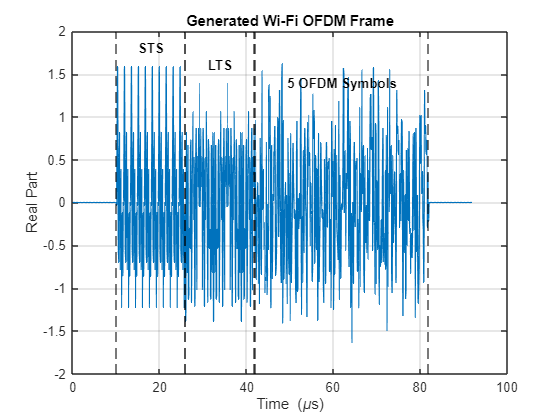

num_ofdm_symbols = 5;
pad_len = 100;

%% (1) Generate a frame with STS, LTS, and 5 OFDM symbols

sts = gen_sts();
lts = gen_lts();
[ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc);

sts = sts / rms(sts);
lts = lts / rms(lts);
ofdm_data = ofdm_data / rms(ofdm_data);

tx_frame = [zeros(pad_len,1); sts; lts; ofdm_data; zeros(pad_len,1)];

region_names = {'STS', 'LTS', '5 OFDM Symbols'};
region_ranges = [
    pad_len + 1,                              pad_len + length(sts);
    pad_len + length(sts) + 1,                pad_len + length(sts) + length(lts);
    pad_len + length(sts) + length(lts) + 1,  pad_len + length(sts) + length(lts) + length(ofdm_data)
];

plot_td_signal(tx_frame, fs, 'Generated Wi-Fi OFDM Frame', 'Real', region_names, region_ranges);


fprintf('(1) STS length   = %d samples (%.2f us)\n', length(sts), length(sts)/fs*1e6);

(1) STS length   = 160 samples (16.00 us)


fprintf('(1) LTS length   = %d samples (%.2f us)\n', length(lts), length(lts)/fs*1e6);

(1) LTS length   = 160 samples (16.00 us)


fprintf('(1) Data length  = %d samples (%.2f us)\n', length(ofdm_data), length(ofdm_data)/fs*1e6);

(1) Data length  = 400 samples (40.00 us)


fprintf('(1) Frame length = %d samples (%.2f us)\n', length(tx_frame), length(tx_frame)/fs*1e6);

(1) Frame length = 920 samples (92.00 us)




%% (2) Transmit the frame and receive it using USRP

capture_len = 3 * length(tx_frame);
tx_repeat_num = ceil(capture_len / length(tx_frame));
tx_waveform = repmat(tx_frame, tx_repeat_num, 1);

[tx_usrp, rx_usrp] = setup_usrp(fc, fs, tx_gain, rx_gain);

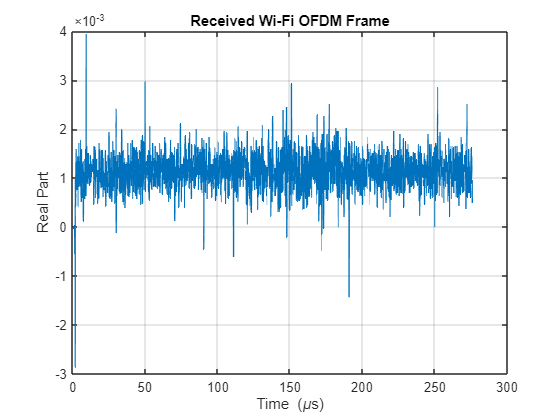

rx_frame = usrp_tx_rx_once(tx_usrp, rx_usrp, tx_waveform, capture_len);

release(tx_usrp);
release(rx_usrp);

plot_td_signal(rx_frame, fs, 'Received Wi-Fi OFDM Frame', 'Real', [], []);

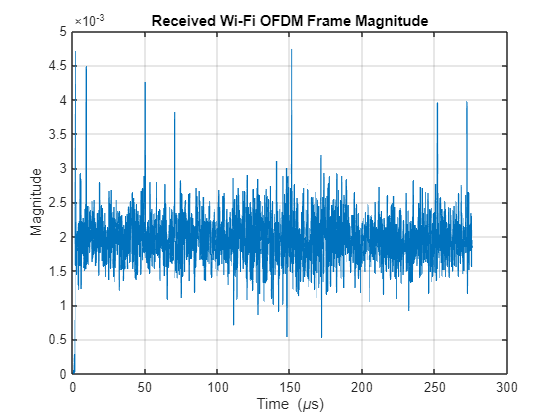

plot_td_signal(rx_frame, fs, 'Received Wi-Fi OFDM Frame Magnitude', 'Abs', [], []);


fprintf('(2) Received frame length = %d samples (%.2f us)\n', length(rx_frame), length(rx_frame)/fs*1e6);

(2) Received frame length = 2760 samples (276.00 us)


fprintf('(2) Max abs(rx_frame)     = %.4f\n', max(abs(rx_frame)));

(2) Max abs(rx_frame)     = 0.0047


fprintf('(2) RMS(rx_frame)         = %.4f\n', rms(rx_frame));

(2) RMS(rx_frame)         = 0.0020




%% (3) Ensure the OFDM sample rate is 10 MHz

master_clock_rate = 100e6;
interp_factor = master_clock_rate / fs;
decim_factor = master_clock_rate / fs;

fprintf('(3) Master clock rate    = %.1f MHz\n', master_clock_rate/1e6);

(3) Master clock rate    = 100.0 MHz


fprintf('(3) Target sample rate   = %.1f MHz\n', fs/1e6);

(3) Target sample rate   = 10.0 MHz


fprintf('(3) Interpolation factor = %d\n', interp_factor);

(3) Interpolation factor = 10


fprintf('(3) Decimation factor    = %d\n', decim_factor);

(3) Decimation factor    = 10


fprintf('(3) Actual TX rate       = %.1f MHz\n', master_clock_rate/interp_factor/1e6);

(3) Actual TX rate       = 10.0 MHz


fprintf('(3) Actual RX rate       = %.1f MHz\n', master_clock_rate/decim_factor/1e6);

(3) Actual RX rate       = 10.0 MHz




%% (4) Apply frame synchronization using matched filter

lts_ref = lts(33:96);
mf_out = abs(conv(rx_frame, flipud(conj(lts_ref))));

[~, peak_idx] = max(mf_out);
first_lts_start = peak_idx - length(lts_ref) + 1;

fprintf('(4) Beginning index of the first long training symbol = %d\n', first_lts_start);

(4) Beginning index of the first long training symbol = 0


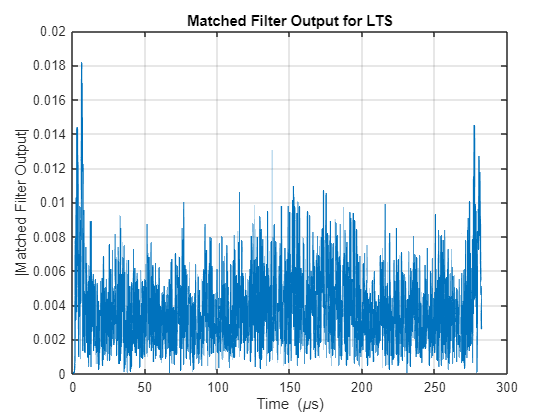


plot_mf_result(mf_out, fs, 'Matched Filter Output for LTS');

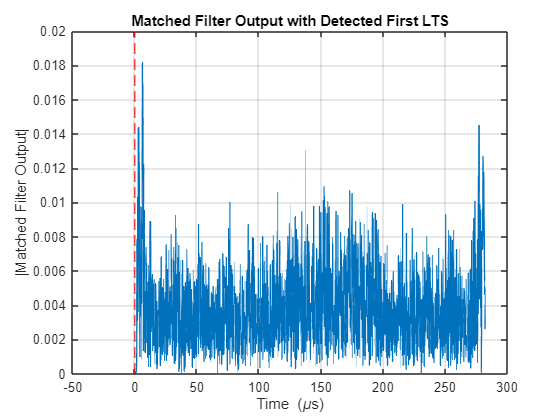


figure;
t_us = (0:length(mf_out)-1).' / fs * 1e6;
plot(t_us, mf_out, 'LineWidth', 1);
grid on;
xlabel('Time (\mus)');
ylabel('|Matched Filter Output|');
title('Matched Filter Output with Detected First LTS');
hold on;
xline((first_lts_start-1)/fs*1e6, '--r', 'LineWidth', 1.2);

% plot_mf_result
% Usage:
%   plot_mf_result(mf_out, fs, fig_title)
% Input:
%   mf_out    : matched filter output
%   fs        : sampling rate in Hz
%   fig_title : figure title
% Output:
%   None
%   This function plots the matched filter output in microseconds
function plot_mf_result(mf_out, fs, fig_title)
    t_us = (0:length(mf_out)-1).' / fs * 1e6;

    figure;
    plot(t_us, mf_out, 'LineWidth', 1);
    grid on;
    xlabel('Time (\mus)');
    ylabel('|Matched Filter Output|');
    title(fig_title);
end